# Simple Spectrogram

- sample bird call audio 

[channels, sample_rate] = audioread('../datasets/XC403881.wav');
whos;

  Name                  Size              Bytes  Class     Attributes

  channels         450879x2             7214064  double              
  sample_rate           1x1                   8  double              



- note there are 2 channels

- play the audio

soundsc(channels, sample_rate);
N = length(channels);
t = (0:N-1)/sample_rate;

- plot the channels

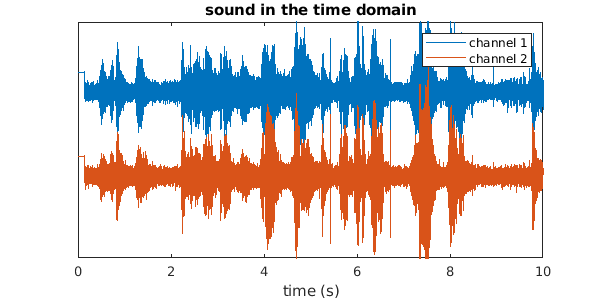

f1 = figure(1); clf;
f1.Position = [0 0 600 300];
plot(t, bsxfun(@plus, channels, [.25 0])); %offset the channels
xlabel("time (s)");
title("sound in the time domain");
xlim([0 10]);
ylim([-.3 .4]);
yticks([]);
legend(["channel 1", "channel 2"]);

- compute and plot the power spectrum

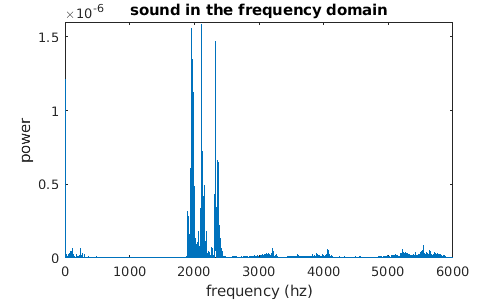

hz_vals = linspace(0, sample_rate/2, floor(N/2)+1);
powers = abs(fft(detrend(channels(:,1)))/N).^2;

f2 = figure(2); clf;
f2.Position = [0 0 500 300];
plot(hz_vals, powers(1:length(hz_vals)));
xlabel("frequency (hz)");
ylabel("power");
title("sound in the frequency domain");
xlim([0 6000]);

## Now Apply spectrogram

- use function in signal processing tool box

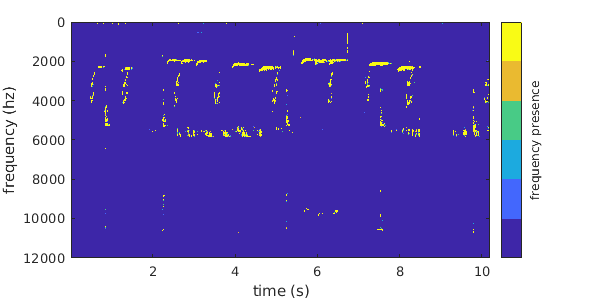

[spectrum, frequency, time] = spectrogram(detrend(channels(:,1)), hann(1000), 100, [], sample_rate);

f3 = figure(3); clf;
f3.Position = [0 0 600 300]; 
imagesc(time, frequency, abs(spectrum).^2);
ax = gca;
ax.CLim = [3 4];
ax.YLim = frequency([1 dsearchn(frequency, 12000)]);
ax.XLim = time([1 end]);
colormap(parula(6));
c = colorbar();
c.Label.String = "frequency presence";
set(c, 'YTick', []);
xlabel("time (s)");
ylabel("frequency (hz)");

### Separate the sources

- visually inspect the spectrogram to identify frequencies of interest

freq_{1} = [1800 2500];
freq_{2} = [2501 5299];
freq_{3} = [5300 5900];

### Plot

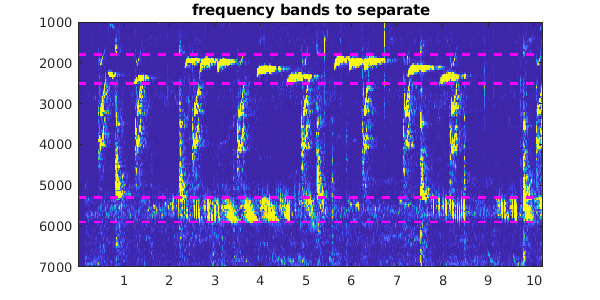

colorz = 'kk';
f4 = figure(4); clf;
f4.Position = [0 0 600 300]; 
imagesc(time, frequency, abs(spectrum).^2);
ylim([1000 7000]);
ax = gca;
ax.CLim = [0 2];
hold on;
for k = 1:length(freq_)
    plot(get(gca,'xlim'), [1 1]*freq_{k}(1), 'm--', 'linew', 2);
    plot(get(gca,'xlim'), [1 1]*freq_{k}(2), 'm--', 'linew', 2);
end
hold off;
title("frequency bands to separate");

### Filter both frequency ranges

filtered_freqs = cell(length(freq_),1);

for k=1:length(freq_)
    order = round(10*sample_rate/freq_{1}(1));
    kernel = fir1(order, freq_{k}/(sample_rate/2));
    
    for l=1:2
        chan = channels(:,l);
        filtered = filtfilt(kernel, 1, chan);
        filtered_freqs{k}(:,l) = filtered;
        
    end
end

### Play and plot the sounds

- original

soundsc(channels, sample_rate);

- lower frequency

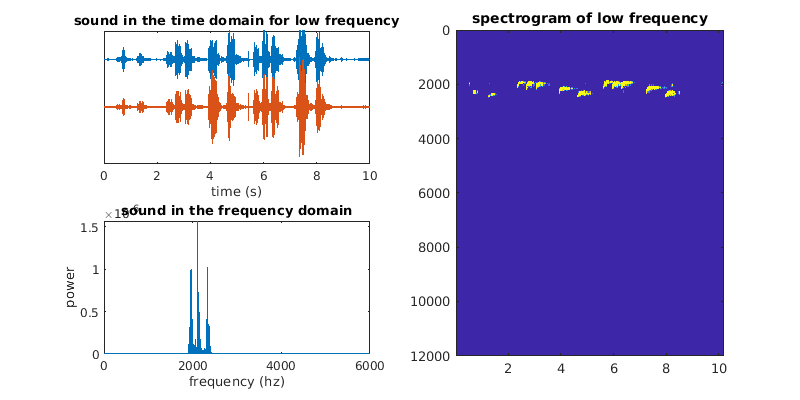

%soundsc(filtered_freqs{1}, sample_rate);
low_powers = abs(fft(detrend(filtered_freqs{1}(:,1)))/N).^2;
[low_spectrum, low_frequency, low_time] = spectrogram(detrend(filtered_freqs{1}(:,1)), hann(1000), 100, [], sample_rate);

f5 = figure(5); clf;
f5.Position = [0 0 800 400];
subplot(221);
plot(t, bsxfun(@plus, filtered_freqs{1}, [.25 0])); %offset the channels
xlabel("time (s)");
title("sound in the time domain for low frequency");
xlim([0 10]);
ylim([-.3 .4]);
yticks([]);

subplot(223);
plot(hz_vals, low_powers(1:length(hz_vals)));
xlabel("frequency (hz)");
ylabel("power");
title("sound in the frequency domain");
xlim([0 6000]);

subplot(2,2,[2;4]);
imagesc(low_time, low_frequency, abs(low_spectrum).^2);
ax = gca;
ax.CLim = [0 4];
ax.YLim = low_frequency([1 dsearchn(low_frequency, 12000)]);
ax.XLim = low_time([1 end]);
colormap(parula(6));
title("spectrogram of low frequency");

- middle frequency

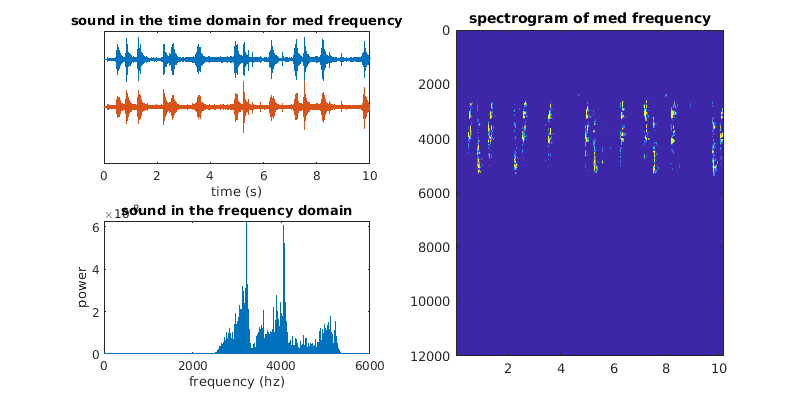

soundsc(filtered_freqs{2}, sample_rate);
med_powers = abs(fft(detrend(filtered_freqs{2}(:,1)))/N).^2;
[med_spectrum, med_frequency, med_time] = spectrogram(detrend(filtered_freqs{2}(:,1)), hann(1000), 100, [], sample_rate);

f5 = figure(5); clf;
f5.Position = [0 0 800 400];
subplot(221);
plot(t, bsxfun(@plus, filtered_freqs{2}, [.25 0])); %offset the channels
xlabel("time (s)");
title("sound in the time domain for med frequency");
xlim([0 10]);
ylim([-.3 .4]);
yticks([]);

subplot(223);
plot(hz_vals, med_powers(1:length(hz_vals)));
xlabel("frequency (hz)");
ylabel("power");
title("sound in the frequency domain");
xlim([0 6000]);

subplot(2,2,[2;4]);
imagesc(med_time, med_frequency, abs(med_spectrum).^2);
ax = gca;
ax.CLim = [0 4];
ax.YLim = med_frequency([1 dsearchn(med_frequency, 12000)]);
ax.XLim = med_time([1 end]);
colormap(parula(6));
title("spectrogram of med frequency");

- higher frequency (don't use headphones)

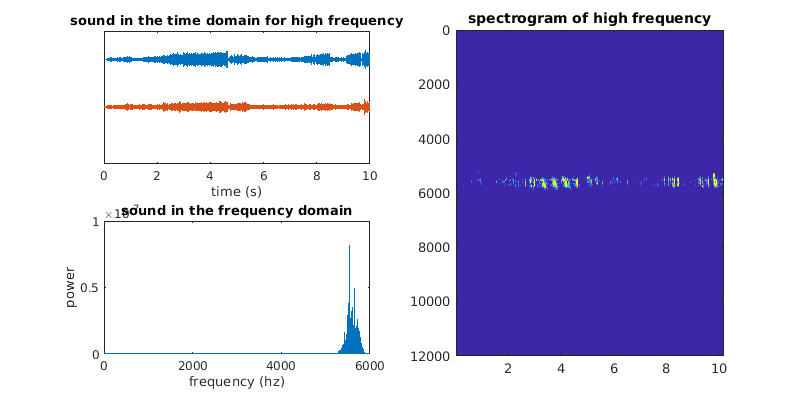

soundsc(filtered_freqs{3}, sample_rate);

high_powers = abs(fft(detrend(filtered_freqs{3}(:,1)))/N).^2;
[high_spectrum, high_frequency, high_time] = spectrogram(detrend(filtered_freqs{3}(:,1)), hann(1000), 100, [], sample_rate);

f5 = figure(5); clf;
f5.Position = [0 0 800 400];
subplot(221);
plot(t, bsxfun(@plus, filtered_freqs{3}, [.25 0])); %offset the channels
xlabel("time (s)");
title("sound in the time domain for high frequency");
xlim([0 10]);
ylim([-.3 .4]);
yticks([]);

subplot(223);
plot(hz_vals, high_powers(1:length(hz_vals)));
xlabel("frequency (hz)");
ylabel("power");
title("sound in the frequency domain");
xlim([0 6000]);

subplot(2,2,[2;4]);
imagesc(high_time, high_frequency, abs(high_spectrum).^2);
ax = gca;
ax.CLim = [0 4];
ax.YLim = high_frequency([1 dsearchn(high_frequency, 12000)]);
ax.XLim = high_time([1 end]);
colormap(parula(6));
title("spectrogram of high frequency");